**Semilog plot**. Over the past 5 years, the number of students in 6.094 has been 15, 25, 55, 115, 144. 

Class size seems like it’s growing exponentially. To verify this, plot these values on a plot with a log y scale and label it (**semilogy**, **xlabel**, **ylabel**, **title**). Use magenta square symbols of marker size 10 and line width 4, and no line connecting them. You may have to change the x limits to see all 5 symbols (**xlim**). If the relationship really is exponential, it will look linear on a log plot.

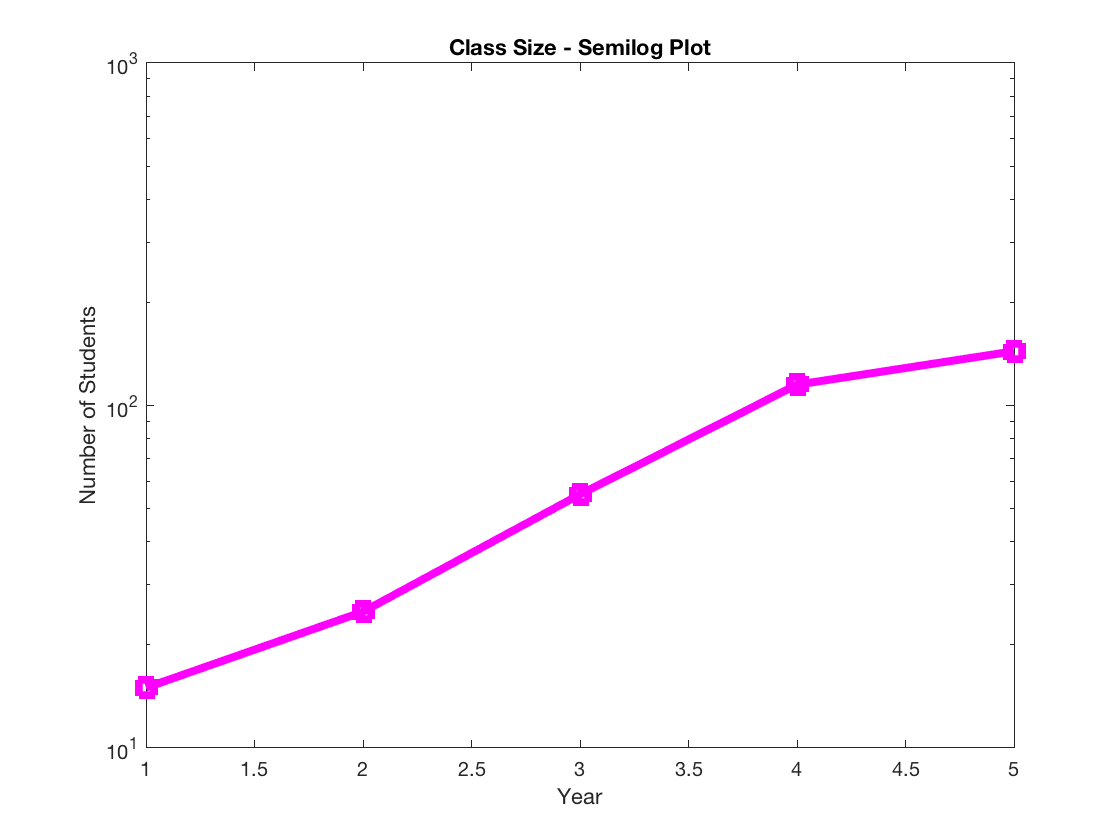

number_of_students = [15, 25, 55, 115, 144];
semilogy(number_of_students,'Color', 'm', 'Marker','square','LineWidth',4,'MarkerSize',10)
xlabel('Year')
ylabel('Number of Students')
title('Class Size - Semilog Plot')

**Bar graph**.  Make  a  vector  of  5  random  values  and  plot  them  on  a  bar  graph  using  red bars.

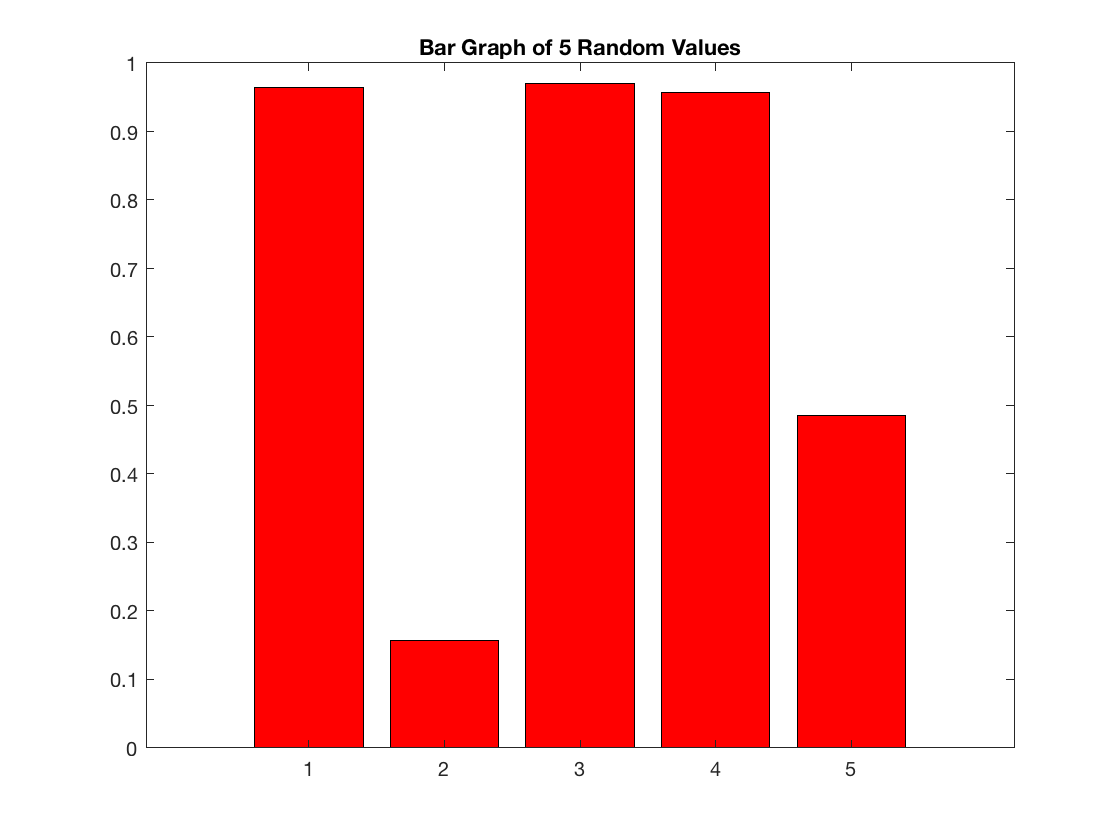

bar(rand(5,1),'grouped','red')
title('Bar Graph of 5 Random Values')

**Interpolation and surface plots. **The accompanying scrip 'randomSurface.m' defines the function generating the graph to the right.

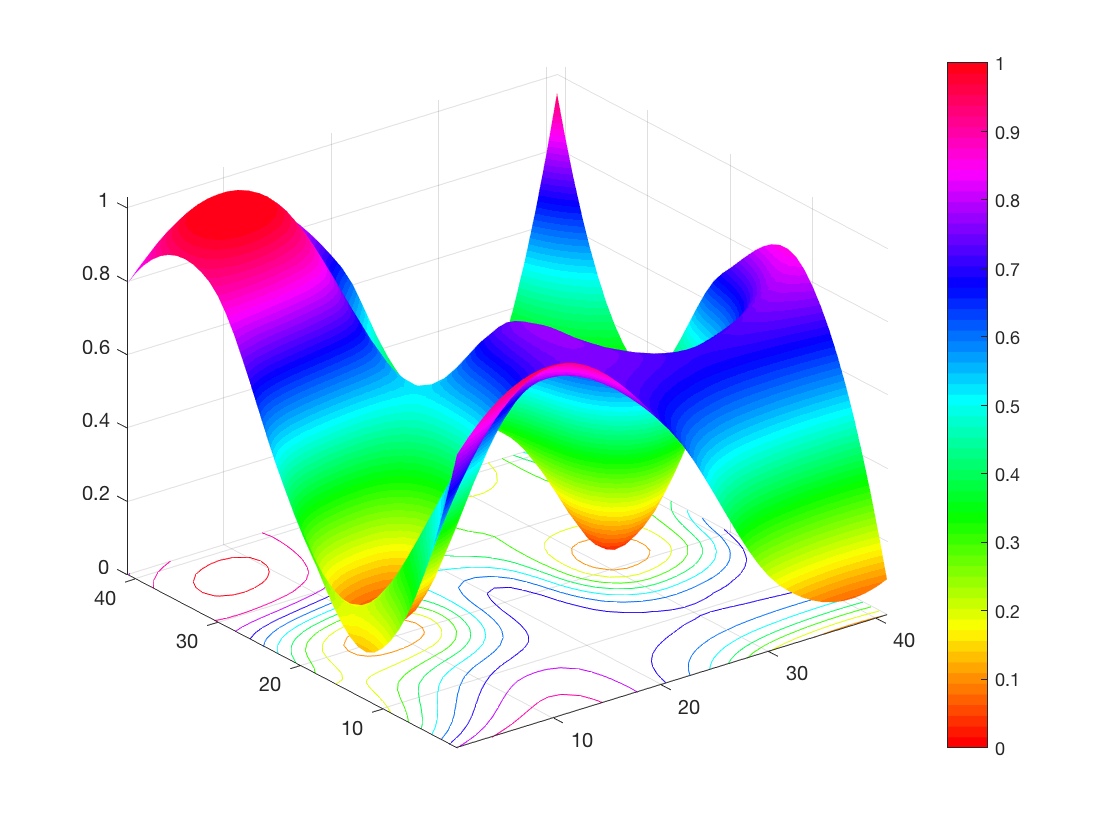

randomSurface

**Fun with find.** Write  a  function  to  return  the  index  of  the  value  that  is  nearest  to  a  desired value.  The  function  declaration  should  be: 

ind=findNearest(x, desiredVal)

Error using Assignment2>x
Too many output arguments.

x is a vector  or  matrix  of  values,  and `desiredVal `is the scalar value you want to find. Do not assume that `desiredVal `exists in `x`, rather find the value that is closest to `desiredVal`. If multiple values are the same distance from `desiredVal`, return all of their indices. Test your function to make sure it works on a few vectors and matrices. Useful functions are abs, min, and find. 

**Hint**: You may have some trouble using `min `when `x `is a matrix. To convert a matrix Q into a  vector  you  can  do  something  like 

y=Q(:)

Then, doing

m=min(y)

will give you the minimum value in `Q`. To find where this minimum occurs in `Q`, do 

inds=find(Q==m);

ind = findNearest(rand(2), 3)

ind = 2

function inds = findNearest(x, desiredVal)
    Q = abs(x - desiredVal);
    y = Q(:);
    m = min(y);
    inds = find(Q==m);
end